# Detect SIFT Features in Image

Read an image.  

I = imread("cameraman.tif");

Detect SIFT features in the image.

points = detectSIFTFeatures(I)

points =   245×1 SIFTPoints array with properties:

          Scale: [245×1 single]
    Orientation: [245×1 single]
         Octave: [245×1 int32]
          Layer: [245×1 int32]
       Location: [245×2 single]
         Metric: [245×1 single]
          Count: 245


Display the location and scale of the 100 strongest points in the image.

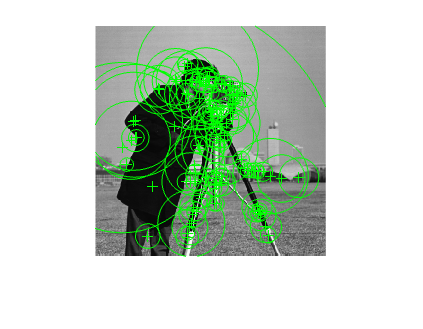

strongest = points.selectStrongest(100);
imshow(I)
hold on
plot(strongest) 

Display the [*x* *y*] coordinates for the selected points.

strongest.Location

ans = 100×2 single matrix
  183.0139  205.4790
  112.5054  206.6145
  135.2954  125.0968
  101.1768  173.8070
  131.3702  113.8461
  167.1152   77.5036
  110.9540  155.9263
  135.0020   92.3701
  112.1106  173.5276
  156.8862   77.8692


Using the detected key points to obtain SIFT feature:

I = imread("cameraman.tif");
points = detectSIFTFeatures(I);
[features,valid_corners] = extractFeatures(I,points);

Display the extracted features

disp(features);

     0     0     9   131   131    13     1     0    13     5    20    68    39    12     7    10     6     4     6     1     0     0     0     3     0     0     0     0     0     0     0     0     3     3    55   131    52    17    11     3    18    16    35    77    51    57    19     9   131    45    31    10     3     4     3    31    17     6     1     0     0     0     0     7    24     5     7     6     4    25    55   103    11     3     3    11    42   131   103    45   131    20     2     2     3    33    62   131    23     9     2    18     3     2    35   110    33    41    57     9     8     6    10    46    30    28    38    15    36    45    33    56    34     5     5    43     5     8    30   131     2     0    23   131     9     2    13    43
     0     2     5     0     1     0     1     0     2    47   126    18     7     5    39     5     2    29   126    29     2     9    71     4     2    11    67    56    46    22    21     3     0     0     7    14     3     1   

display corners

disp(valid_corners);

  311×1 SIFTPoints array with properties:

          Scale: [311×1 single]
    Orientation: [311×1 single]
         Octave: [311×1 int32]
          Layer: [311×1 int32]
       Location: [311×2 single]
         Metric: [311×1 single]
          Count: 311

